# Praktikum 5

Einlesen der Bilder:

img = imread("(11).jpg");
imgDis = imread("11_dis.jpg");

Keypoints finden und abspeichern:

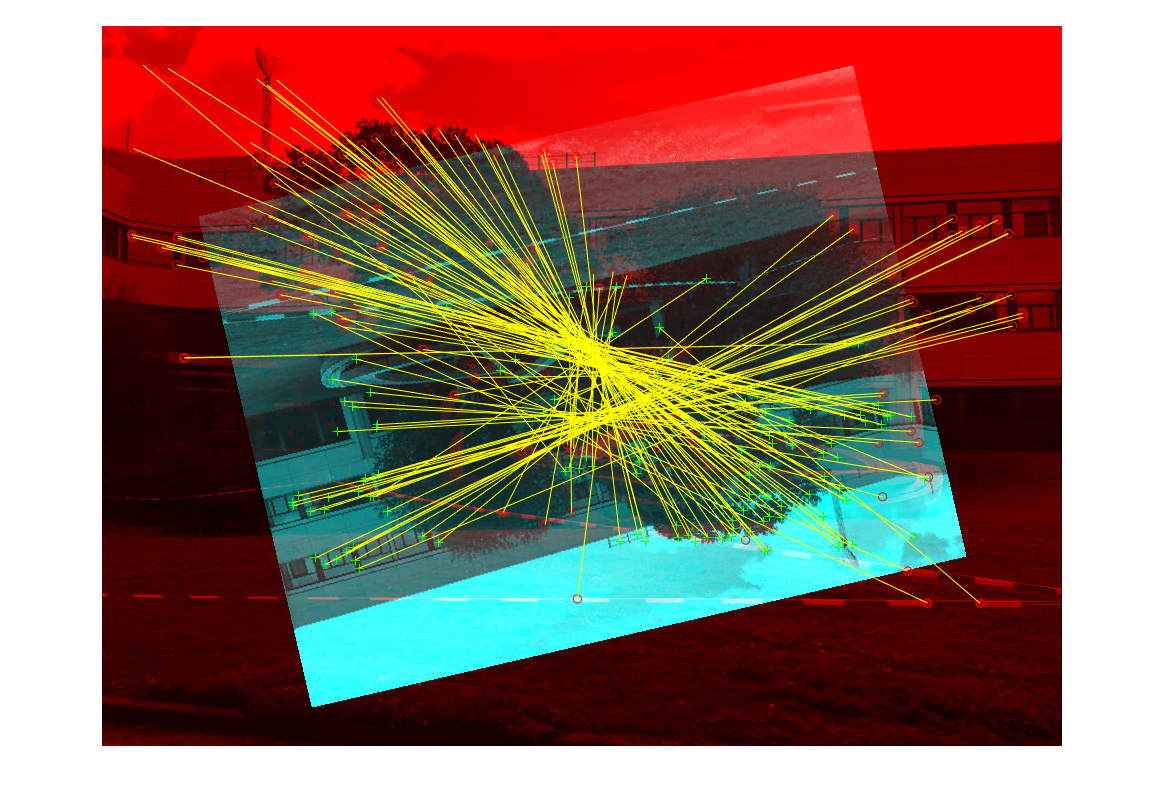

imgGray = rgb2gray(img);
imgDisGray = rgb2gray(imgDis);

SURFimg = detectSURFFeatures(imgGray);
SURFimgDis = detectSURFFeatures(imgDisGray);

[extractedSURFimg, validPointsImg] = extractFeatures(imgGray, SURFimg);
[extractedSURFimgDis, validPointsImgDis] = extractFeatures(imgDisGray, SURFimgDis);

indexPairs = matchFeatures(extractedSURFimg, extractedSURFimgDis);

matchedPointsImg = validPointsImg(indexPairs(:, 1), :);
matchedPointsImgDis = validPointsImgDis(indexPairs(:, 2), :);

figure; showMatchedFeatures(img, imgDis, matchedPointsImg, matchedPointsImgDis)

Transformation schaetzen:

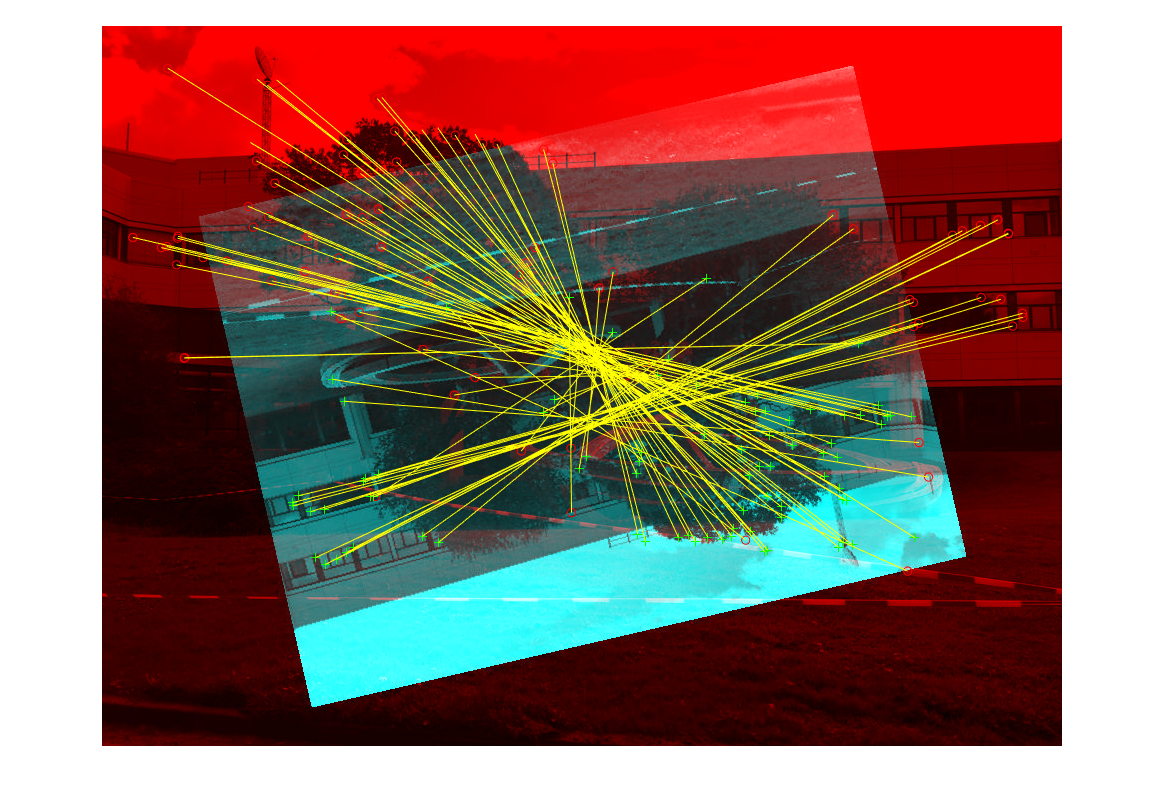

[tform, inlierIdx] = estimateGeometricTransform2D(matchedPointsImgDis, matchedPointsImg, 'similarity');
inlierPtsDis = matchedPointsImgDis(inlierIdx, :);
inlierPts = matchedPointsImg(inlierIdx, :);
figure
showMatchedFeatures(img, imgDis, inlierPts, inlierPtsDis)

Skalierung und Rotationswinkel berechnen:

u = [0 1];
v = [0 0];

[x, y] = transformPointsForward(tform, u, v);
dx = x(2) - x(1);
dy = y(2) - y(1);
angle = (180/pi) * atan2(dy, dx)

angle = single
-167.0111

scale = 1 / sqrt(dx^2 + dy^2)

scale = single
0.6996

Original wieder herstellen:

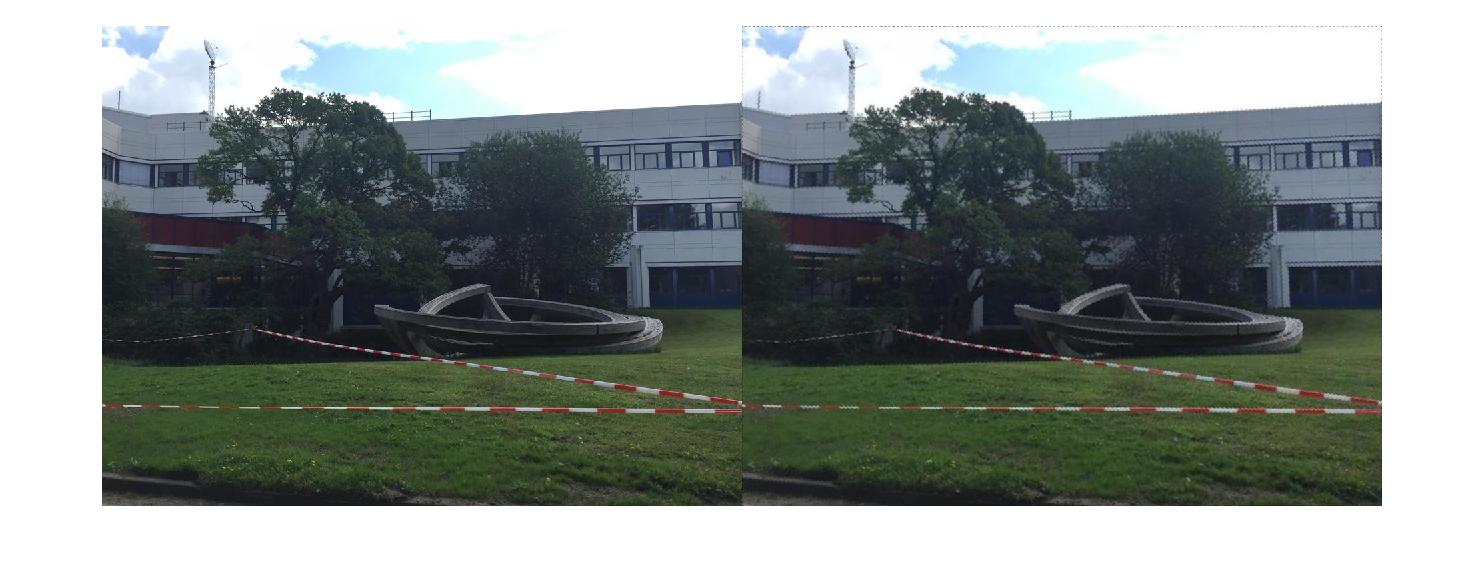

outputView = imref2d(size(img));
Ir = imwarp(imgDis, tform, 'OutputView', outputView);
figure
imshowpair(img, Ir, 'montage')